# 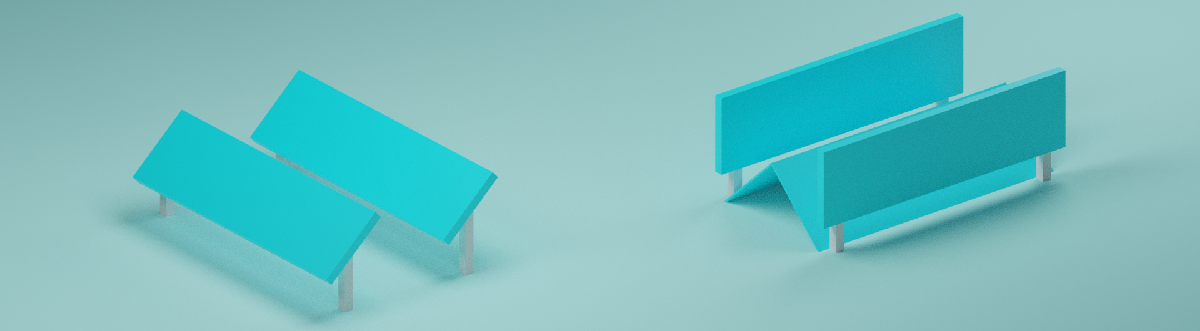

# PVMAPS

This folder contains the PVMAPS simulator. The simulator will allow you to simulate the energy yield potential of solar farms anywhere in the world. Current version supports the following solar farm configurations: (i) systems with fixed-tilted c-Si monofacial (left) and  (ii) systems with vertical bifacial modules with ground-sculpting (right). The simulator requires MATLAB (version > 2016a) to be installed on your computer. 

In this example, we will use the PVMAPS simulator to simulate a *fixed-tilt* solar farm employing c-Si monofacial solar modules. 

### Setting up a simulation

 To initiate a simulation, call the **initate()** function. This will generate the default simulation configuration containing all the parameters you may define in your simulation. 

clc, clear all, close all; 
addpath('pvmaps');  % This line is always required. 'pvmaps' folder must be present in your current directory. 

% Initiate PV-MAPS
input = initiate();         % Initiate the default simulation parameters
input                       

input = struct with fields:
    module: [1×1 struct]
     array: [1×1 struct]
       sim: [1×1 struct]
       lat: 40.4237
       lon: 86.9212


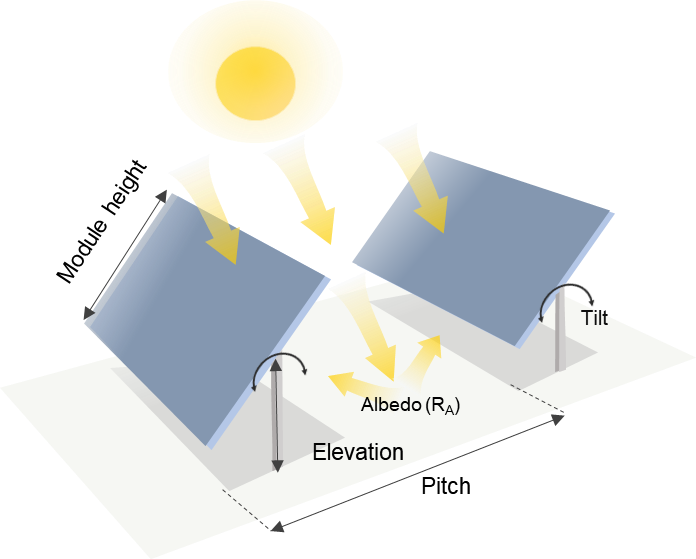

Before running a simulation, we will customize the design parameters of our solar farm. This will be done by overwriting  the  default parameters in the  **input **variable**.**  If not overwritten, the default values defined in **input** after initilization will be used. Let us simulate a solar farm consisting of vertically tilted bifacial modules. 

#### Cell & module attributes

% Cell and Module parameters are defined within a substructure called
% 'module'
input.module.cell_tech = 'AL_BSF';   % Name of the cell technology;
input.module.height = 1;             % in m
input.module.stc_eff.direct = 20;    % direct collection efficiency
input.module.stc_eff.diffuse = 20;   % diffuse collection efficiency
input.module.tcoeff = 0.0041;        % Module power temperature coefficient

#### Array geometry

% Cell & module attributes
% Cell and Module parameters are defined within a substructure called
% 'module'
% Supported technologies: 'AL_BSF', 'BI_PERC', 'SHJ', 'PVK_SI_2T', 'PVK_SI_4T', 'SHJ_NN'
input.module.cell_tech = 'AL_BSF';  % Name of the cell technology;
input.module.height = 4.8;             % in m
input.module.stc_eff.direct = 21.8;    % direct collection efficiency
input.module.stc_eff.diffuse = 21.8;   % diffuse collection efficiency
input.module.tcoeff = 0.0041;        % Module power temperature coefficient

% Array geometry
% Array parameters are defined within a substructure called 'array'
input.array.config = 'tracking';       % 'fixed' or 'GSVBF'
input.array.tilt = 25;              % in degrees
input.array.azimuth = 90;          % in degrees 90 = E/W facing, 180 = N/S facing
input.array.albedo = 0.3;           % [0, 1]
input.array.pitch = 11;              % [0, inf) in m
input.array.gsHeight = .5;          % For ground-sculpted systems
input.array.elevation = 3;          % in m

% Coordinate of the solar farm in degrees. 
% Positive for North or East, negative for South or West cardinal directions. 
% Coordinates are defined as variables 
input.lat = 41.26 ;
input.lon = -86.53;

#### Coordinate of the solar farm (in degrees)

Maybe change it to your hometown. 

% Positive for North or East, negative for South or West cardinal directions. 
% Coordinates are defined as variables

input.lat = 32.692;   % Yuma, Arizona         
input.lon = -114.627;

We will define some additional simulator parameters. 

% Simulator parameters
% Simulator parameters are defined within a substructure called 'sim'
input.sim.max_parallel_worker = 0;      % 0 to execute on a single CPU core.
input.sim.quickSim = true;              % Set false for 365-day simulation (slower)

input.sim.save_simdat = true;           % Save detailed sim results including intermediate data
input.sim.save_lightpattern = false;      % Save the irradiance map on the ground between the rows

### Running the simulation for a single location

Finally, to run a solar farm simulation, call **simulate function **with your customized inputs.

output = simulate(input);

██████  ██    ██       ███    ███  █████  ██████  ███████
██   ██ ██    ██       ████  ████ ██   ██ ██   ██ ██      
██████  ██    ██ █████ ██ ████ ██ ███████ ██████  ███████
██       ██  ██        ██  ██  ██ ██   ██ ██           ██
██        ████         ██      ██ ██   ██ ██      ███████
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
Photovoltaic Farm Modeling and Analysis Simulator by Purdue
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
Preparing...
Simulating: 100%    [..........] Complete!


Plot the computed monthly yield potential of the solar farm. 

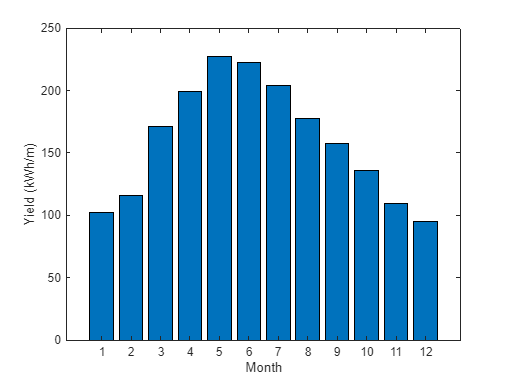

figure();
bar(output.monthly_yield);
xlabel('Month');
ylabel('Yield (kWh/m)');

% To save the figure and result
% exportgraphics(gca, 'Monthly_yield.png')
% save('sim_result.mat', 'output');

disp('DONE!');

DONE!
